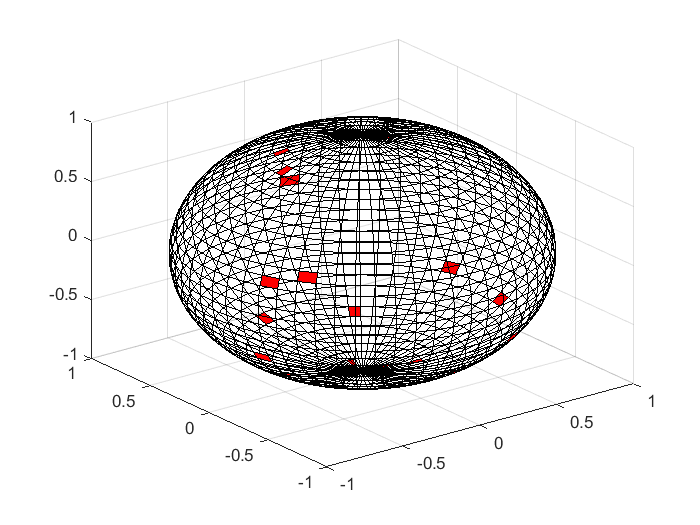

%%%-给定一个xm，ym，zm对应的一组theta和fai-%%%%
clc;
clear;
Mt=40;%theta划分次数
Mf=60;%fai划分次数
t=linspace(0,pi,Mt);
p=linspace(0,2*pi,Mf);
[theta_sphere,phi]=meshgrid(t,p);
x=sin(theta_sphere).*sin(phi);
y=sin(theta_sphere).*cos(phi);
z=cos(theta_sphere);
surf(x,y,z,'FaceAlpha','0');
%%%%%%%%%%%%-测试程序-随机撒点-%%%%%%%%%%%%%
N=20;%点个数
%%%-设定theta1，fai1-%%%%
theta_rand =  pi.*rand(N,1);%%%随机点
fai_rand = 2.*pi.*rand(N,1);%%%随机点
z2rand = cos(theta_rand); 
which_segment = zeros(N,2);
Aq_count = 0;%涂色面片计数；
%%%-针对一个点的灵活度计算-%%%
for ii0 = 1:1:N
    %which_segment每个元素为对应随机角度theta_rand所在区间位置；
    num_t = length(t(t<theta_rand(ii0)));
    num_f = length(p(p<fai_rand(ii0)));
    which_qujian = [num_t num_f];
    if ~ismember(which_qujian,which_segment)
        Aq_count =  Aq_count + 1;%如果当前坐标序号还没有涂过色，则计数+1
    end
    which_segment(ii0,:) = which_qujian;
    d_theta = t(2)-t(1);
    d_fai = p(2)-p(1);
    theta_test=[t(num_t) t(num_t) t(num_t)+d_theta t(num_t)+d_theta];
    fai_test = [p(num_f) p(num_f)+d_fai p(num_f)+d_fai p(num_f)];
    x_ = sin(theta_test).*sin(fai_test);
    y_ = sin(theta_test).*cos(fai_test);
    z_ = cos(theta_test);
    patch(x_,y_,z_,'red');
    %hold on;
end

%view(60,30)
As_all = Mt.*Mf;
%%%-某位置的灵巧度-%%%
D_P = Aq_count./As_all;

%%%%-假设有NUMBER个样本点-%%%
NUMBER = 50000;
D_t = (sum(Aq_count))./(NUMBER.*As_all);%全局灵活度<1!!!

%%%-算法优化-寻找最佳s0与s1比值%%%

